2-1

clc;
clear;
close all;
%2.1.a
%%2.1.a
x = [1, 2, 3]; %the samle x
h = [4, 3, 2, 1];%the samole h
myconv(x,h)

ans =      4    11    20    14     8     3


conv(x,h)

ans =      4    11    20    14     8     3


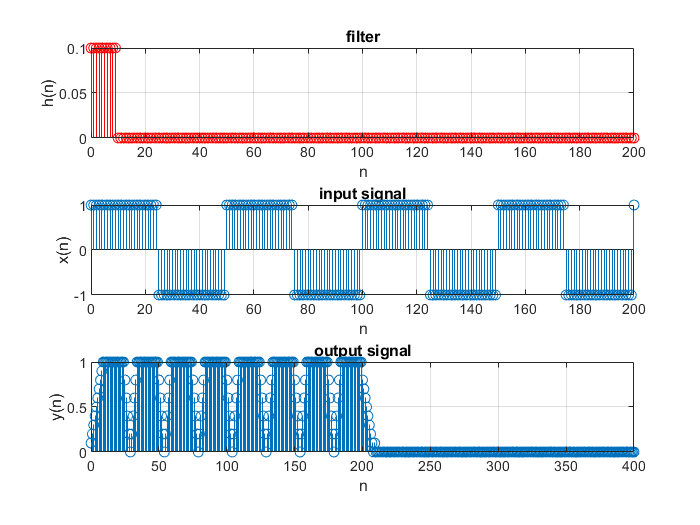


%%2.1.b

n = 0:200;
k = 50;
f = 1/k;
h = zeros(1, length(n));
h(1:10) = 0.1 * 1;
x = square(2 * pi * f * n);
y = myconv(h, x);

figure(1);
subplot(3,1,1);
stem(n, h,'r');
xlabel('n') ;
ylabel('h(n)') ;
title('filter') ;
grid on ;

subplot(3,1,2);
stem(n, x);
xlabel('n') ;
ylabel('x(n)') ;
title('input signal') ;
grid on ;

subplot(3,1,3);
stem(0:length(y) - 1, abs(y));
xlabel('n') ;
ylabel('y(n)') ;
title('output signal') ;
grid on ;

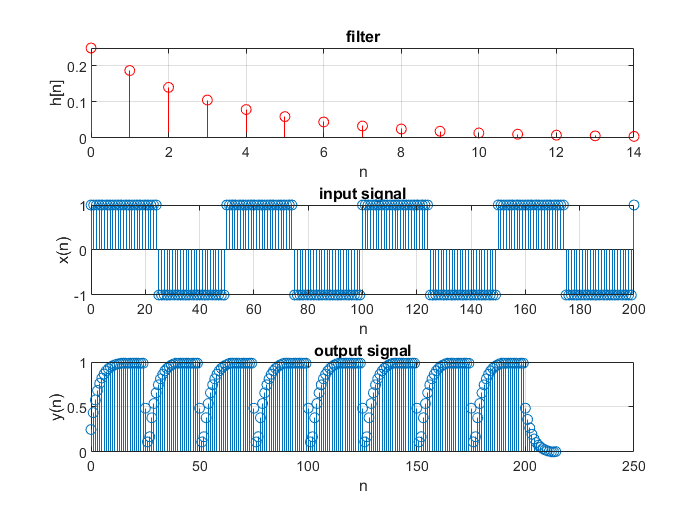

%2.1.c

n = 0:14;
h = 0.25 * 0.75.^n;
y = myconv(h, x);

figure(2);
subplot(3,1,1);
stem(n, h,'r');
xlabel('n') ;
ylabel('h[n]') ;
title('filter') ;
grid on ;

subplot(3,1,2);
stem(0:length(x) - 1, x);
xlabel('n') ;
ylabel('x(n)') ;
title('input signal') ;
grid on ;

subplot(3,1,3);
stem(0:length(y) - 1, abs(y));
xlabel('n') ;
ylabel('y(n)') ;
title('output signal') ;
grid on ;

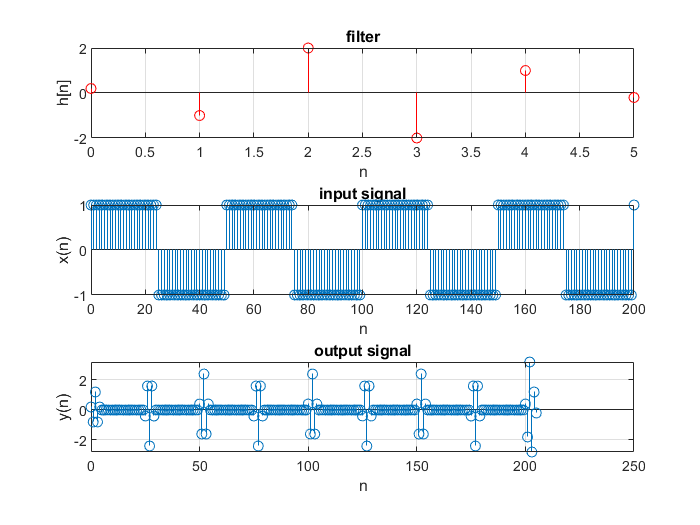

%2.1.d

hn = 0.2*[1,-5,10,-10,5,-1];
y = myconv(hn, x);

figure(3);
subplot(3,1,1);
stem(0:length(hn) - 1, hn,'r');
xlabel('n') ;
ylabel('h[n]') ;
title('filter') ;
grid on ;

subplot(3,1,2);
stem(0:length(x) - 1, x);
xlabel('n') ;
ylabel('x(n)') ;
title('input signal') ;
grid on ;

subplot(3,1,3);
stem(0:length(y) - 1, y);
xlabel('n') ;
ylabel('y(n)') ;
title('output signal') ;
grid on ;

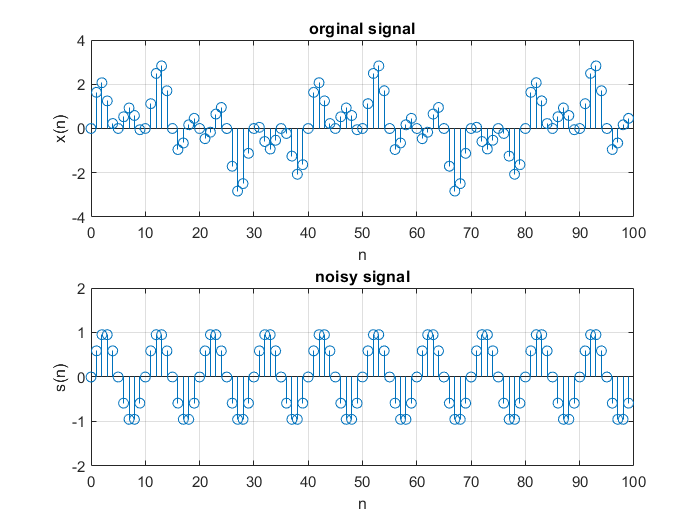

%2.2.a

M  = 100;
n  = 0 : M - 1;
w1 = 0.05 * pi;
w2 = 0.20 * pi;
w3 = 0.35 * pi;
wa = 0.15 * pi;
wb = 0.25 * pi;


s  = sin(w2 * n);
v  = sin(w1 * n) + sin (w3 * n);
x  = s + v;

w  = 0.54 - 0.46 * sin(2 * pi * n / M);
h  = w .* ( wb * sinc(wb * (n - M/2)/pi)/pi - wa * sinc(wa * (n - M/2)/pi)/pi );

figure(4);
subplot(2,1,1);
stem(n, x);
xlabel('n') ;
ylabel('x(n)') ;
title('orginal signal') ;
grid on ;

subplot(2,1,2);
stem(n, s);
xlabel('n') ;
ylabel('s(n)') ;
ylim([-2,2])
title('noisy signal') ;
grid on ;

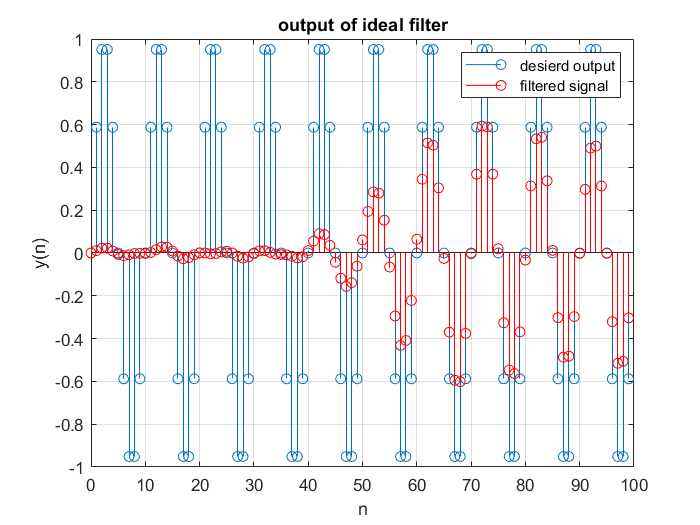



%2.2.b

y = filter(h,1,x);

figure(5);

stem(n, s);
xlabel('n') ;
ylabel('') ;
grid on ;
hold on;

stem(n, y,'r');
xlabel('n') ;
ylabel('y(n)') ;
title('output of ideal filter') ;
grid on ;
legend( 'desierd output','filtered signal ')

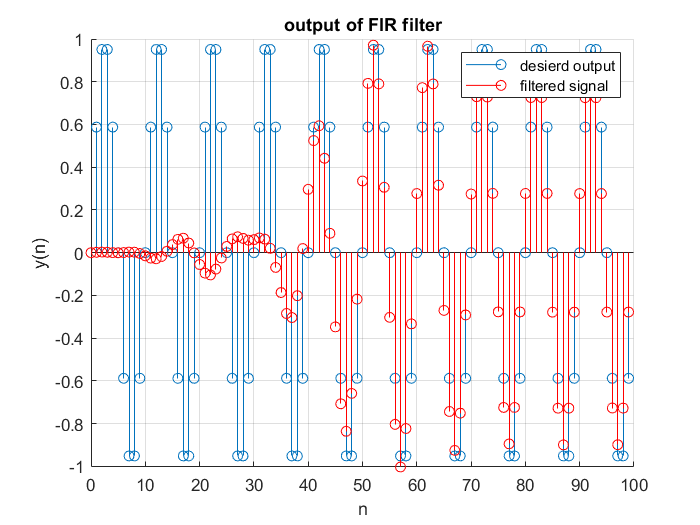



%2.2.c
figure(7);
load('C:\Users\Rayanafshan\Desktop\2-1_2-2\Filter1.mat');
y = filter(Num,1,x);
 
hold on;
stem(n, s);
xlabel('n') ;
ylabel('s(n)') ;
grid on ;


stem(n, y,'r');
xlabel('n') ;
ylabel('y(n)') ;
title('output of FIR filter') ;
grid on ;
legend( 'desierd output','filtered signal ')

function y = myconv(h,x)
M = length(h);
L = length(x);
N = M + L - 1;
X = [x, zeros(1,M)];
H = [h, zeros(1,L)];
y = zeros(1, N);
if(M > L)
    temp = X;
    X    = H;
    H    = temp;
end
for ii = 1 : N
    for jj = 1 : min(L, M)
        if (ii - jj + 1 > 0)
            y(ii) = y(ii) + H(jj) * X(ii - jj + 1);
        end
    end
end
end